# **Identification du système à régler et synthèse du régulateur de courant**

clc;
clear;
close all;
s = tf('s');

## Paramètres

% Données du moteur synchrone
Tn  = 3.3;       % Couple nominal [Nm]
In  = 4.5;       % Courant nominal efficace [A]
U12 = 45;        % Tension efficace à 1000rpm = 1000*2*pi/60 rad/s [V]
R   = 2.7;       % Résistance [Ohm]
L   = 9e-3;      % Inductance [H]
Jm  = 0.24e-3;   % Inertie moteur [kgm^2]

Jt = 4.0230e-04; % Inertie totale
Ke = 0.3509;     % Constante de vitesse
Kt = 0.5185;     % Constante de couple
tau_e = 3.3e-3;  % Constante de temps électrique
tau_m = 6e-3;    % Constante de temps mécanique

% Données du variateur
Kcm = 1;         % Gain [-]
Tr  = 1.17e-4;   % Retard pur [s] (manuellement déterminé sysquake)
Tau_cm = Tr;

% Données de l'organe de mesure de courant
Kmi = 1;         % Gain [-]
tau_mi = 1/(2*pi*800);  % Constante de temps [s] (déterminée manuellement sysquake)

% Fonction de transfert
Kai = Kcm*Kmi*Jt/(Kt*Ke)*1.04; % C'est quoi ce 1.04, déterminé après coup
Gai = (Kcm*exp(-s*Tr)) * Kai * (s/(1 + s*tau_m + s^2*tau_m*tau_e)) * (Kmi/(1 + s*tau_mi));

## 3.

Déterminer la constante de temps dominante équivalente du système à régler (tau dom).

tau_dom = 1/36; %pic de fréquence caractéristique/pulsation -> prendre son inverse constante de temps dom équivalente

## 4.

Déterminer la somme des petites constantes de temps

TpE = tau_mi + Tau_cm;

## 5.

Ecrire un programme permettant de tracer l'évolution de la bande passante et de l'erreur statique en fonction du facteur N.

% OK

## 6.

Pour une marge de phase de 45°, trouver le facteur N qui représente un bon compromis* entre erreur statique et bande passante.

*tradeof entre rapidité et erreur statique (à justifié)

Déterminer les paramètres du régulateur PI

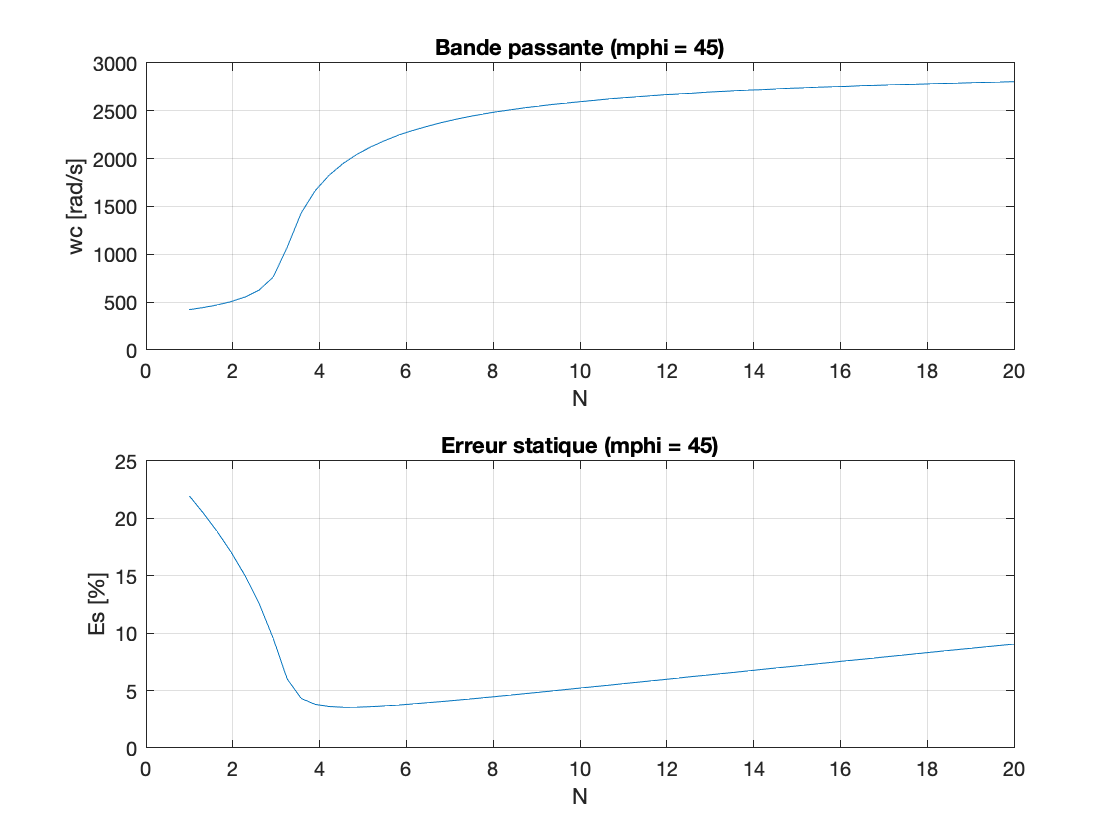

% Marge de phase de 45°
mphi     = 45;
w        = logspace(1,4,5000);
Nmin     = 1;
Nmax     = 20;
Ncourbes = 60;

% Calcul des params en fonction de N
[N, wc, Gain, phase, Kpi, Tii, Es] = regul_pi(Gai, Kai, TpE, mphi, w, Nmin, Nmax, Ncourbes);

% Affichage bande passante fct. de N (= rapidité de régulation)
figure;
subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom, title('Bande passante (mphi = 45)');

% Affichage erreur statique fct. de N
subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom, title('Erreur statique (mphi = 45)');


%subplot(3,1,3), plot(N, Kpi), xlabel('N'), ylabel('Kpi [-]'), grid, zoom;

% Sélection N
N_m45 = 6;

% Meilleurs paramamètres
[Kpi_m45, Tii_m45] = compute_PI_params(Gai, TpE, N_m45, mphi);

fprintf("Marge de phase %.1f, N = %.1f -> Kpi = %f, Tii = %f", mphi, N_m45, Kpi_m45, Tii_m45);

Marge de phase 45.0, N = 6.0 -> Kpi = 19.261520, Tii = 0.001896

## 7.

Répeter la démarche pour une marge de phase de 60°.

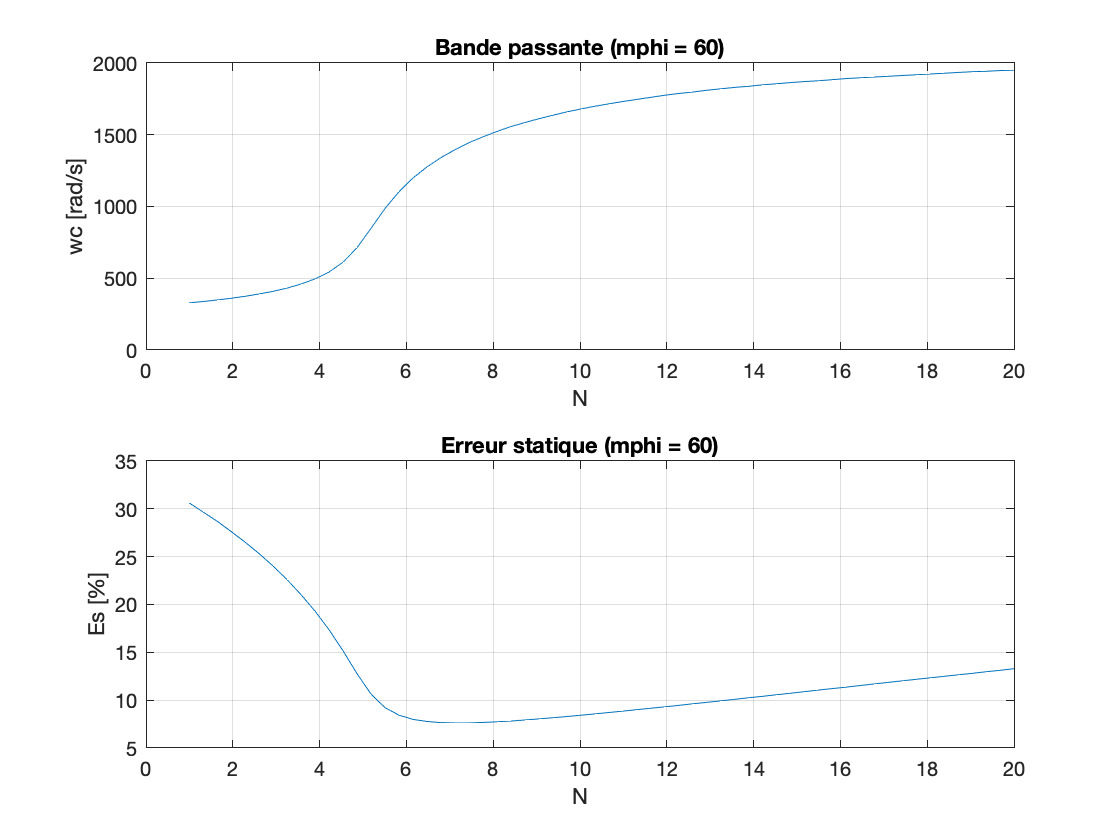

% Marge de phase de 45°
mphi     = 60;
w        = logspace(1,4,5000);
Nmin     = 1;
Nmax     = 20;
Ncourbes = 60;

% Calcul des params en fonction de N
[N, wc, Gain, phase, Kpi, Tii, Es] = regul_pi(Gai, Kai, TpE, mphi, w, Nmin, Nmax, Ncourbes);

% Affichage bande passante fct. de N
figure;
subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom, title('Bande passante (mphi = 60)');

% Affichage erreur statique fct. de N
subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom, title('Erreur statique (mphi = 60)');


% Sélection N
N_m60 = 8;

% Meilleurs paramamètres
[Kpi_m60, Tii_m60] = compute_PI_params(Gai, TpE, N_m60, mphi);

fprintf("Marge de phase %.1f, N = %.1f -> Kpi = %f, Tii = %f", mphi, N_m60, Kpi_m60, Tii_m60);

Marge de phase 60.0, N = 8.0 -> Kpi = 11.416955, Tii = 0.002528

## 8.

Commenter les résultats obtenus pour ces deux régulateurs PI (45° et 60° de marge de phase).

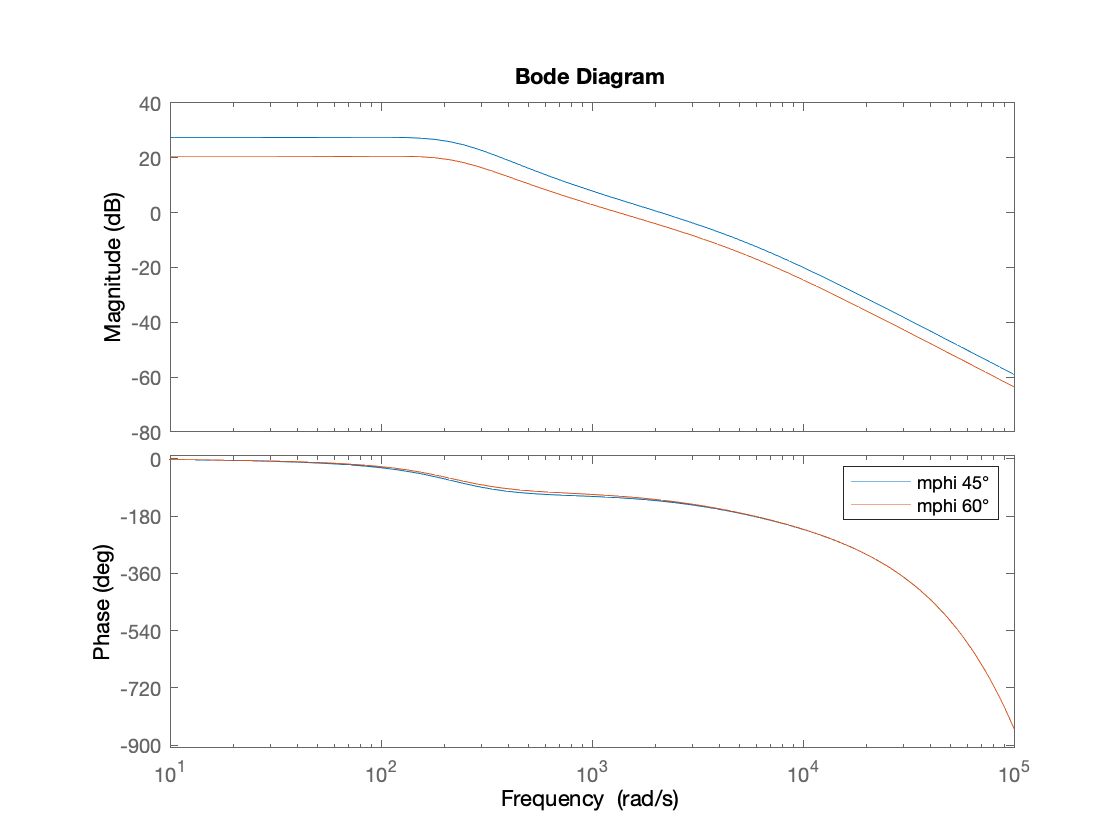

% Diagramme de bode des deux régulateurs
figure;
Gri = tf(Kpi_m45*[Tii_m45 1], [Tii_m45 0]);    
Goi = Gri*Gai;                              
bode(Goi);                               
hold on;
Gri = tf(Kpi_m60*[Tii_m60 1], [Tii_m60 0]);    
Goi = Gri*Gai;                              
bode(Goi);
legend('mphi 45°', 'mphi 60°')
hold off;



%plot(N, Kpi), xlabel('N'), ylabel('Kpi [-]'), grid, zoom;
%subplot(2,1,1), semilogx(w, Gain), xlabel('w [rad/s]'), ylabel('Goi [dB]'), ylim([-40 40]);
%subplot(2,1,2), semilogx(w, phase), xlabel('w [rad/s]'), ylabel('phi [°]'), ylim([-180 0]);

%subplot(2,1,1), plot(N, wc), xlabel('N'), ylabel('wc [rad/s]'), grid, zoom;
%subplot(2,1,2), plot(N, Es*100), xlabel('N'), ylabel('Es [%]'), grid, zoom;